ex.14: Calcule pelas regras de Neuber e Linear as tensões \Sigma e as deformações \Epsilon geradas por \Sigma_{n} = { 0 ---> \Sigma_{n} ---> 0} na raiz de um entalhe com Kt=3 numa placa de um material epse de Sy = 400 MPa e E = 200 GPa, para (1) \Sigma_{n} = 100, (2) \Sigma_{n} = 200 e (3) \Sigma_{n} = 300 MPa.

clear all;close all;clc;
R = 1;
r1 = 1;
Sigma_N = 400;
theta = linspace(0, 2*pi, 3600);

Representando as tensões de Kirsh:

Sigma_R = (Sigma_N/2) * ((1 - (R/r1)^2) + (1 - (4*R^2)/(r1^2) + (3*R^4)/(r1^4)) * cos(2*theta));
Sigma_th = (Sigma_N/2) * ((1 + (R/r1)^2) - (1 + (3*R^4)/(r1^4)) * cos(2*theta));
Tal_th = -(Sigma_N/2) * (1 + (2*R^2)/(r1^2) - (3*R^4)/(r1^4)) * sin(2*theta);

Representação do furo e da Tensão de Von Mises:

furo = r1*sin(theta).^2 + r1*cos(theta).^2;
furo_exterior = (R + 0.5) * ones(size(theta));
Sigma_VM = sqrt(Sigma_R.^2 + Sigma_th.^2 - Sigma_R.*Sigma_th + 3*Tal_th.^2);

Estimando as ZPs :

zp_75Sy = 0.75 * Sigma_VM / Sigma_N;
zp_50Sy = 0.50 * Sigma_VM / Sigma_N;
zpr_75Sy = 0.75 * Sigma_VM / (2 * Sigma_N);
LE = Sigma_VM / (3 * Sigma_N);

Plotango as figuras:

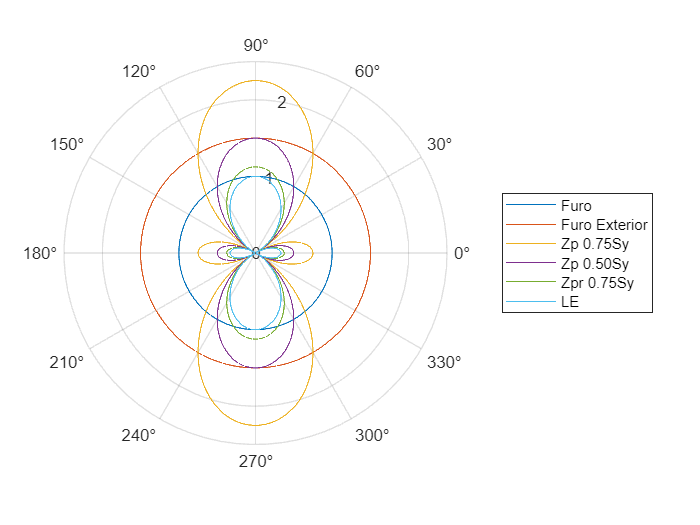

figure();
polarplot(theta, furo, theta, furo_exterior, theta, zp_75Sy, theta, zp_50Sy, theta, zpr_75Sy, theta, LE)
legend('Furo', 'Furo Exterior', 'Zp 0.75Sy', 'Zp 0.50Sy', 'Zpr 0.75Sy', 'LE')